clear; clc;
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex');
set(0,'defaultLegendInterpreter','latex');

% note after 5 degree's Ackeret (linear theory) performs poorly, but shock
% expansion does not

alphas = [0,1,3];
%alphas = [0,10,15];
%alphas = [15];
num_alphas = length(alphas);

%M=3;
Mach=[1.2:0.05:2.5];
Chord = 1;
%theta_half = 10
%toverc = 100*2*0.5*Chord*tand(theta_half); %IT"S A PERCENT!
toverc = 10;%

% Starting the Shock Expansion initialisation
%M_out=zeros(num_alphas,1);
%P_out=zeros(num_alphas,1);
Coef_L_SE=zeros(num_alphas,length(alphas));
Coef_D_SE=zeros(num_alphas,length(alphas));

% Starting the Linear Theory initialisation
%Coef_L_LT=zeros(num_alphas,1);
%Coef_D_LT=zeros(num_alphas,1);

for j = 1:length(Mach)
    M = Mach(j)
for AoA_i = 1:num_alphas
    alphas(AoA_i)
    % Calculating the Shcok-Expansion CL and CD for the alpha series
    %[M_out,P_out,Coef_L_SE(AoA_i), Coef_D_SE(AoA_i)] = ShockExpansion_Diamond(M,Chord,toverc,alphas(AoA_i));
    [Coef_L_SE(AoA_i,j), Coef_D_SE(AoA_i,j)] = ShockExpansion_Diamond(M,Chord,toverc,alphas(AoA_i));
    
    % Calculating the Ackeret (linear theory) CL and CD for the alpha series
    %[Coef_L_LT(AoA_i), Coef_D_SE_LT(AoA_i)] = LinearTheorey_Diamond(3,1,10,AoA_i);
    %[C_Lplt(AoA_i),C_Dw_LTplt(AoA_i)] = LinearTheory_Plate(M,alfa)
    
end
end

M = 1.2000

ans = 0

ans = 1

ans = 3

M = 1.2500

ans = 0

ans = 1

ans = 3

M = 1.3000

ans = 0

ans = 1

ans = 3

M = 1.3500

ans = 0

ans = 1

ans = 3

M = 1.4000

ans = 0

ans = 1

ans = 3

M = 1.4500

ans = 0

ans = 1

ans = 3

M = 1.5000

ans = 0

ans = 1

ans = 3

M = 1.5500

ans = 0

ans = 1

ans = 3

M = 1.6000

ans = 0

ans = 1

ans = 3

M = 1.6500

ans = 0

ans = 1

ans = 3

M = 1.7000

ans = 0

ans = 1

ans = 3

M = 1.7500

ans = 0

ans = 1

ans = 3

M = 1.8000

ans = 0

ans = 1

ans = 3

M = 1.8500

ans = 0

ans = 1

ans = 3

M = 1.9000

ans = 0

ans = 1

ans = 3

M = 1.9500

ans = 0

ans = 1

ans = 3

M = 2

ans = 0

ans = 1

ans = 3

M = 2.0500

ans = 0

ans = 1

ans = 3

M = 2.1000

ans = 0

ans = 1

ans = 3

M = 2.1500

ans = 0

ans = 1

ans = 3

M = 2.2000

ans = 0

ans = 1

ans = 3

M = 2.2500

ans = 0

ans = 1

ans = 3

M = 2.3000

ans = 0

ans = 1

ans = 3

M = 2.3500

ans = 0

ans = 1

ans = 3

M = 2.4000

ans = 0

ans = 1

ans = 3

M = 2.4500

ans = 0

ans = 1

ans = 3

M = 2.5000

ans = 0

ans = 1

ans = 3


%%%%%%%%%
%OUTPUT%
%%%%%%%%%
Coef_L_SE

Coef_L_SE =    -0.0000         0         0    0.0000         0    0.0000   -0.0000    0.0000    0.0000         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000         0    0.0000   -0.0000         0         0         0
   -0.0005    0.1472    0.1275    0.0919    0.0795    0.0717    0.0660    0.0616    0.0579    0.0547    0.0522    0.0497    0.0476    0.0457    0.0440    0.0424    0.0410    0.0396    0.0384    0.0373    0.0362    0.0352    0.0344    0.0335    0.0327    0.0319    0.0312
    0.1769    0.2522    0.3152    0.3703    0.2465    0.2191    0.2002    0.1860    0.1746    0.1650    0.1568    0.1495    0.1432    0.1375    0.1323    0.1275    0.1233    0.1193    0.1156    0.1122    0.1089    0.1061    0.1032    0.1007    0.0981    0.0959    0.0936


Coef_D_SE

Coef_D_SE =     0.0837    0.0867    0.0528    0.0463    0.0421    0.0389    0.0363    0.0342    0.0323    0.0307    0.0293    0.0280    0.0269    0.0258    0.0249    0.0240    0.0232    0.0225    0.0218    0.0211    0.0205    0.0199    0.0194    0.0189    0.0184    0.0180    0.0176
    0.0837    0.0738    0.0591    0.0485    0.0437    0.0403    0.0376    0.0353    0.0334    0.0317    0.0302    0.0289    0.0277    0.0266    0.0257    0.0248    0.0239    0.0232    0.0224    0.0218    0.0212    0.0206    0.0200    0.0195    0.0190    0.0186    0.0181
    0.0771    0.0796    0.0822    0.0847    0.0578    0.0518    0.0477    0.0445    0.0419    0.0397    0.0378    0.0361    0.0346    0.0332    0.0320    0.0309    0.0298    0.0289    0.0280    0.0272    0.0264    0.0257    0.0250    0.0244    0.0237    0.0232    0.0226


%M_out
%P_out
%%%%%%%%%

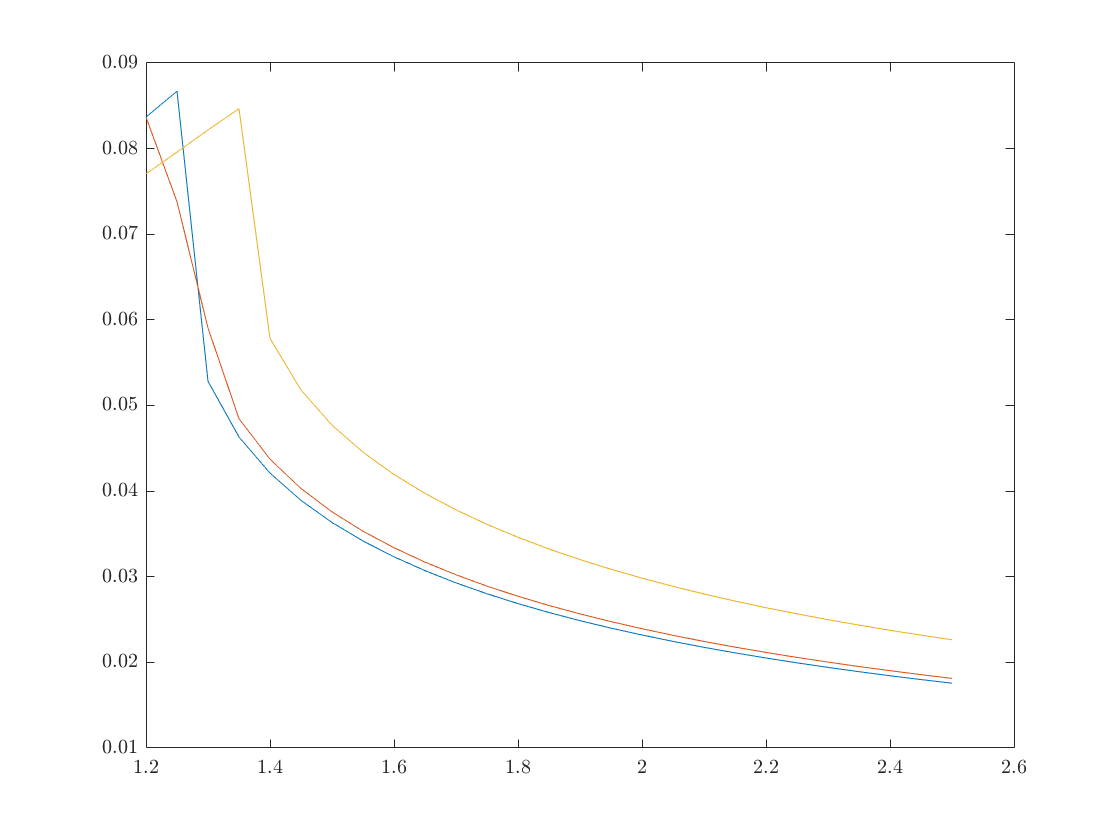

plot(Mach,Coef_D_SE)

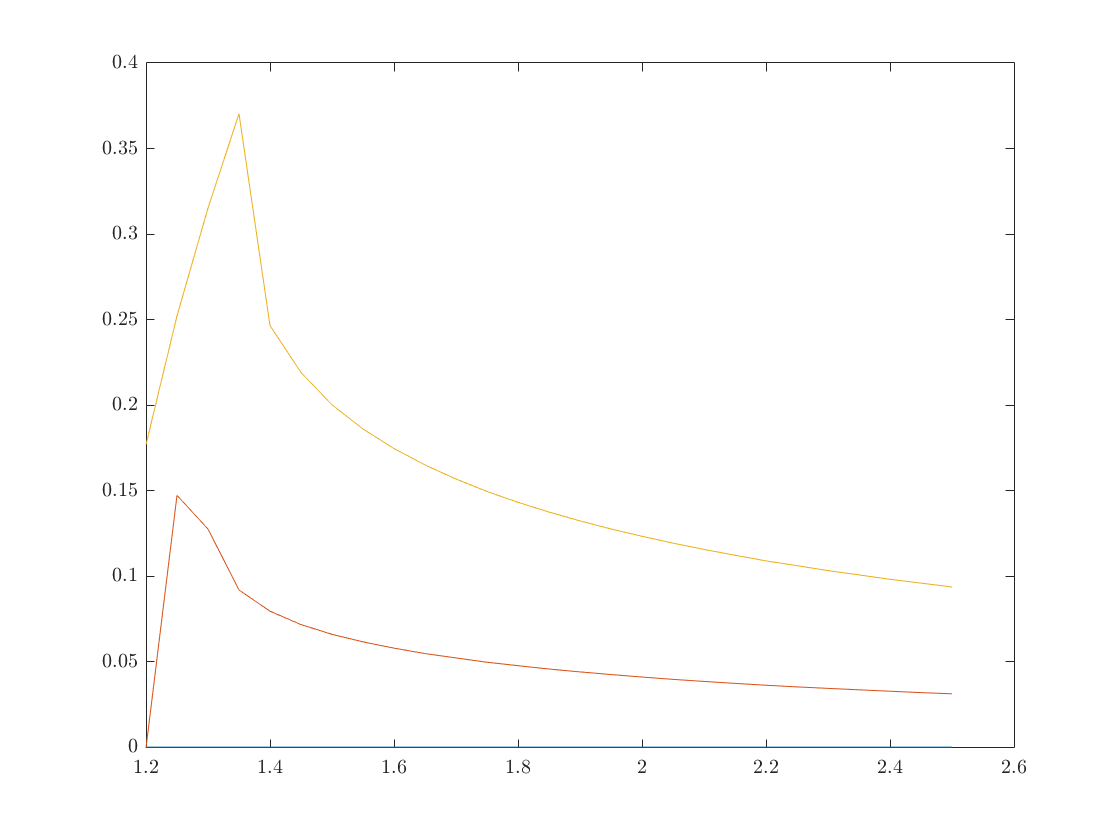

plot(Mach,Coef_L_SE)

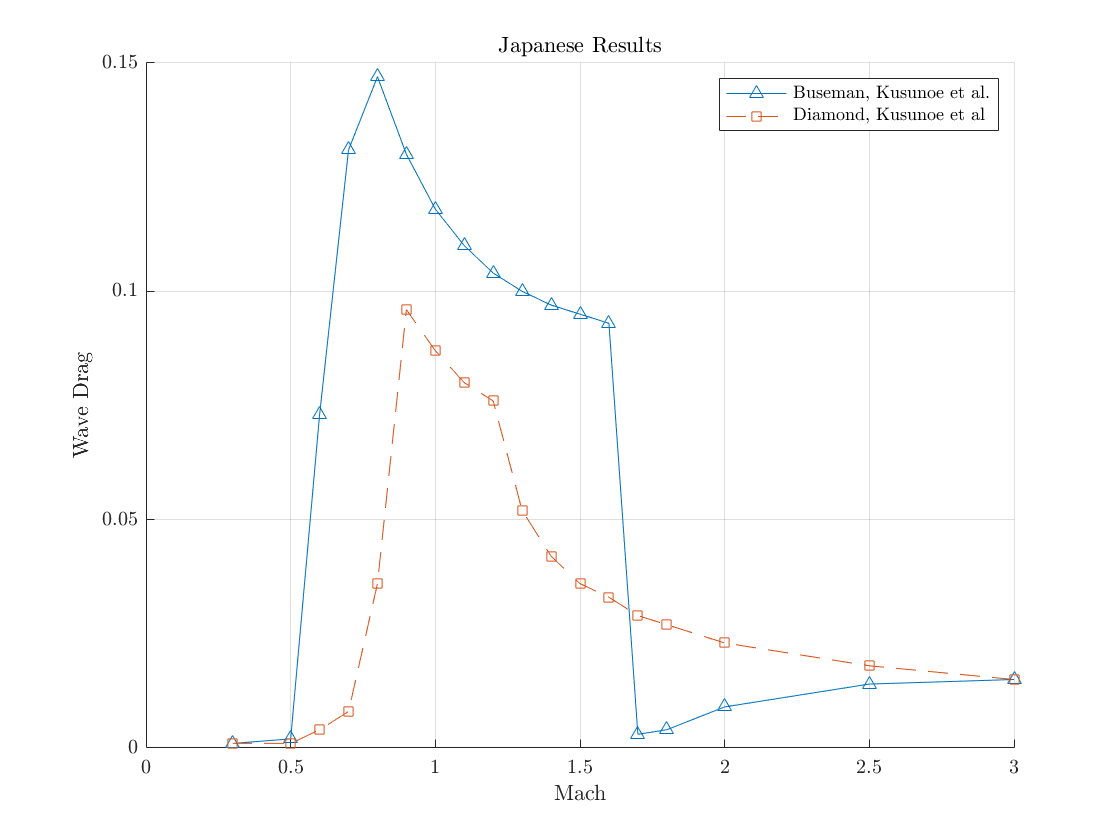

%Flat Plate
Coef_L_flat = 4.*deg2rad(alphas)./(sqrt(M^2-1));
Coef_Dw_flat = 4.*((deg2rad(alphas)).^2)./(sqrt(M^2-1));

LoverD_SE = Coef_L_SE./Coef_D_SE;
LoverD_flat = Coef_L_flat./Coef_Dw_flat;
%LoverD_LT = Coef_L_LT./Coef_D_LT;
%LoverD_flat = Coef_L_flat./Coef_D_flat;

%%%%%%%%%%%%%%
%%%%%%%%%%%%%%
% THESE NEED UPDATING POTENTIALLY!!!
%%%%%%%%%%%%%%
MachRuns = [0.3,0.5:0.1:1.8, 2, 2.5, 3];
Jpn_Busemann = [0.001,0.002,0.073,0.131,0.147,0.13,0.118,0.110,0.104,0.1,0.097,0.095,0.093,0.003,0.004,0.009,0.014,0.015];
Jpn_Diamond = [0.001,0.001,0.004,0.008,0.036,0.096,0.087,0.080,0.076,0.052,0.042,0.036,0.033,0.029,0.027,0.023,0.018,0.015];
%%%%%%%%%%%%%%
Jpn_alphas = [0:0.5:3.5];
Jpn_dia_cl_euler =[0,0.0257,0.0515,0.0773,0.1031,0.1290,0.1550,0.1810];
Jpn_dia_cdw_euler =[0.02891, 0.02914, 0.02983, 0.0316, 0.03264, 0.03475, 0.03734, 0.04041];
Jpn_dia_LoverD_euler =Jpn_dia_cl_euler./Jpn_dia_cdw_euler;
%%%%%%%%%%%%%%
%%%%%%%%%%%%%%

figure
plot(MachRuns,Jpn_Busemann,'^-')
hold on
plot(MachRuns,Jpn_Diamond,'s--')
xlabel("Mach")
ylabel("Wave Drag")
title("Japanese Results")
legend("Buseman, Kusunoe et al.","Diamond, Kusunoe et al", "Location","northeast","NumColumns",1)
box off
grid on
hold off

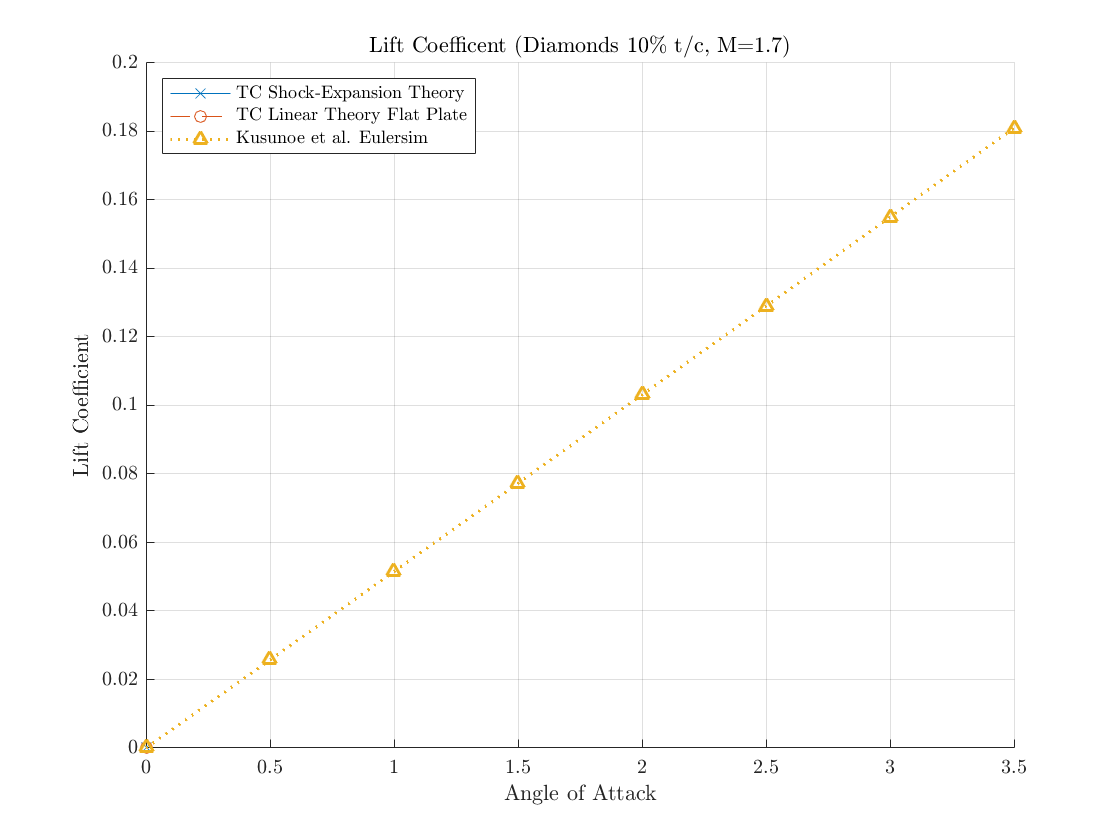


figure
plot(alphas,Coef_L_SE,'x-')
hold on
plot(alphas,Coef_L_flat,'o--')
hold on
plot(Jpn_alphas,Jpn_dia_cl_euler,'^:','LineWidth',1.5)
%plot(alphas,Coef_L_LT,'x')
%plot(alphas,Coef_L_flat,'x')
xlabel("Angle of Attack")
ylabel("Lift Coefficient")
title("Lift Coefficent (Diamonds 10\% t/c, M=1.7)")
legend("TC Shock-Expansion Theory","TC Linear Theory Flat Plate", "Kusunoe et al. Eulersim", "Location","northwest","NumColumns",1)
box off
grid on
hold off

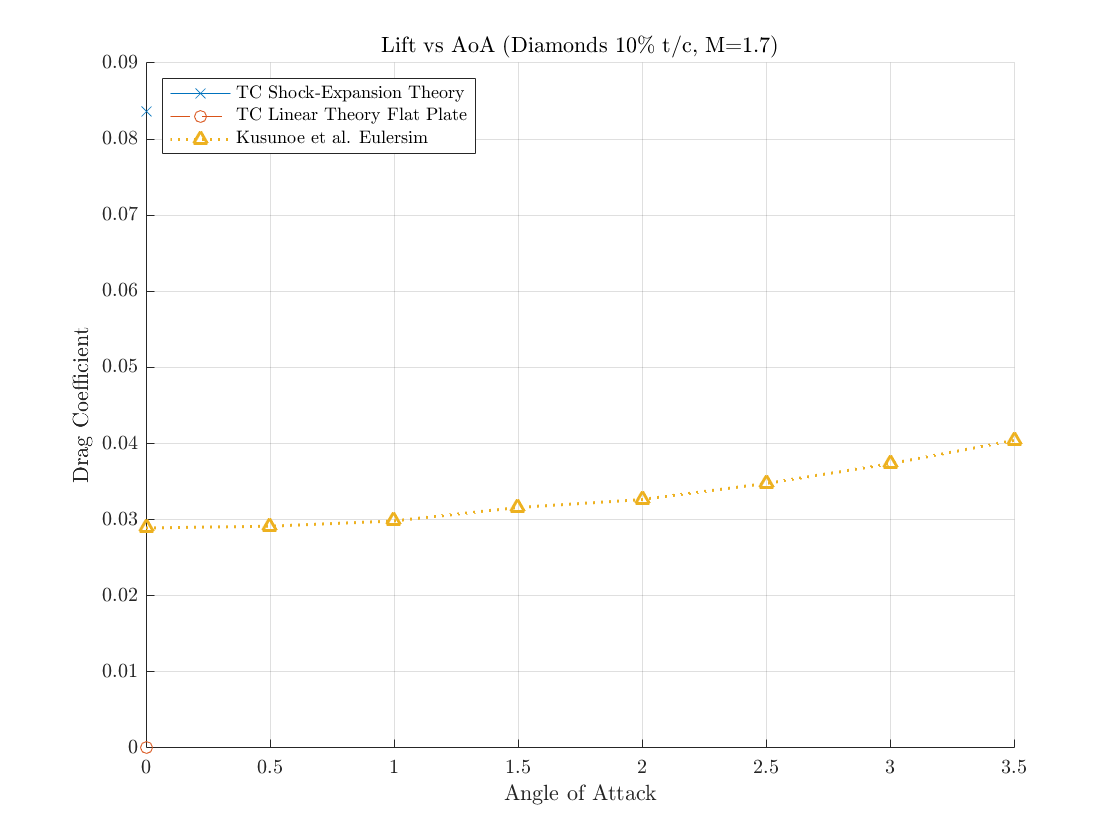


figure
plot(alphas,Coef_D_SE,'x-')
hold on
plot(alphas,Coef_Dw_flat,'o--')
hold on
plot(Jpn_alphas,Jpn_dia_cdw_euler,'^:','LineWidth',1.5)
xlabel("Angle of Attack")
ylabel("Drag Coefficient")
title("Lift vs AoA (Diamonds 10\% t/c, M=1.7)")
legend("TC Shock-Expansion Theory","TC Linear Theory Flat Plate", "Kusunoe et al. Eulersim", "Location","northwest","NumColumns",1)
box off
grid on
hold off

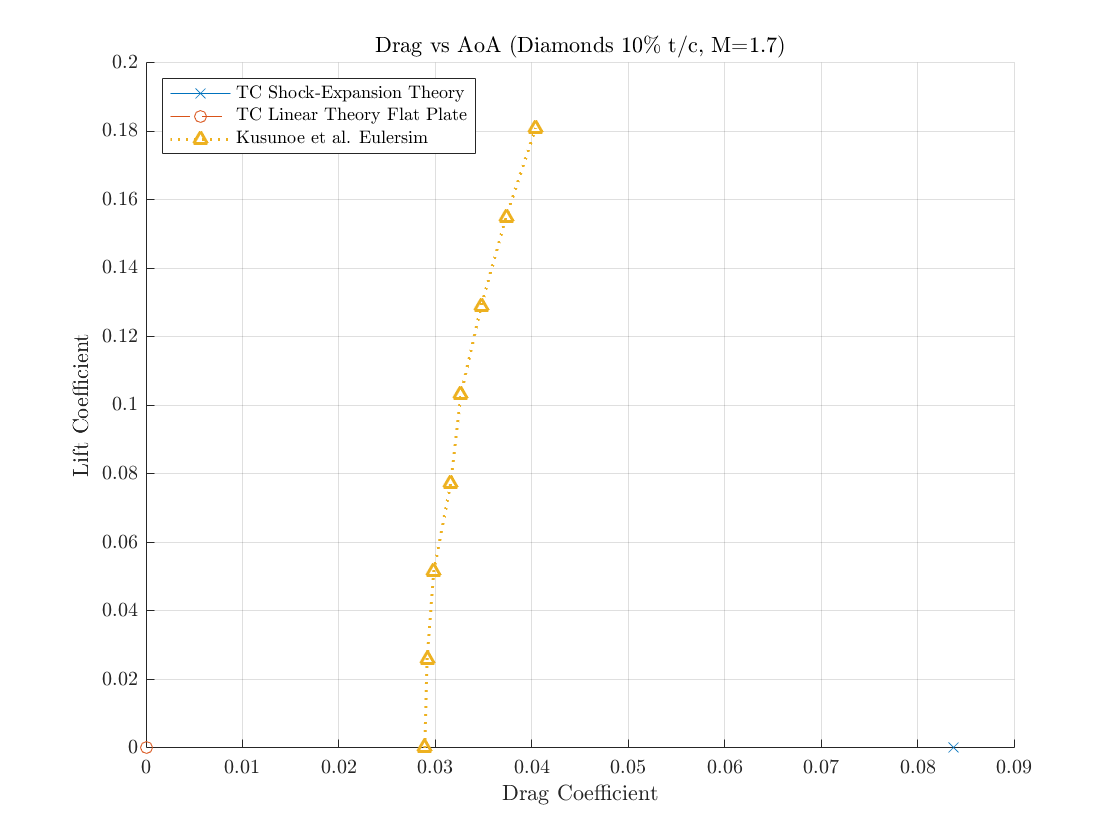


figure
plot(Coef_D_SE,Coef_L_SE,'x-')
hold on
plot(Coef_Dw_flat,Coef_L_flat,'o--')
hold on
plot(Jpn_dia_cdw_euler,Jpn_dia_cl_euler,'^:','LineWidth',1.5)
xlabel("Drag Coefficient")
ylabel("Lift Coefficient")
title("Drag vs AoA (Diamonds 10\% t/c, M=1.7)")
legend("TC Shock-Expansion Theory","TC Linear Theory Flat Plate", "Kusunoe et al. Eulersim", "Location","northwest","NumColumns",1)
box off
grid on
hold off

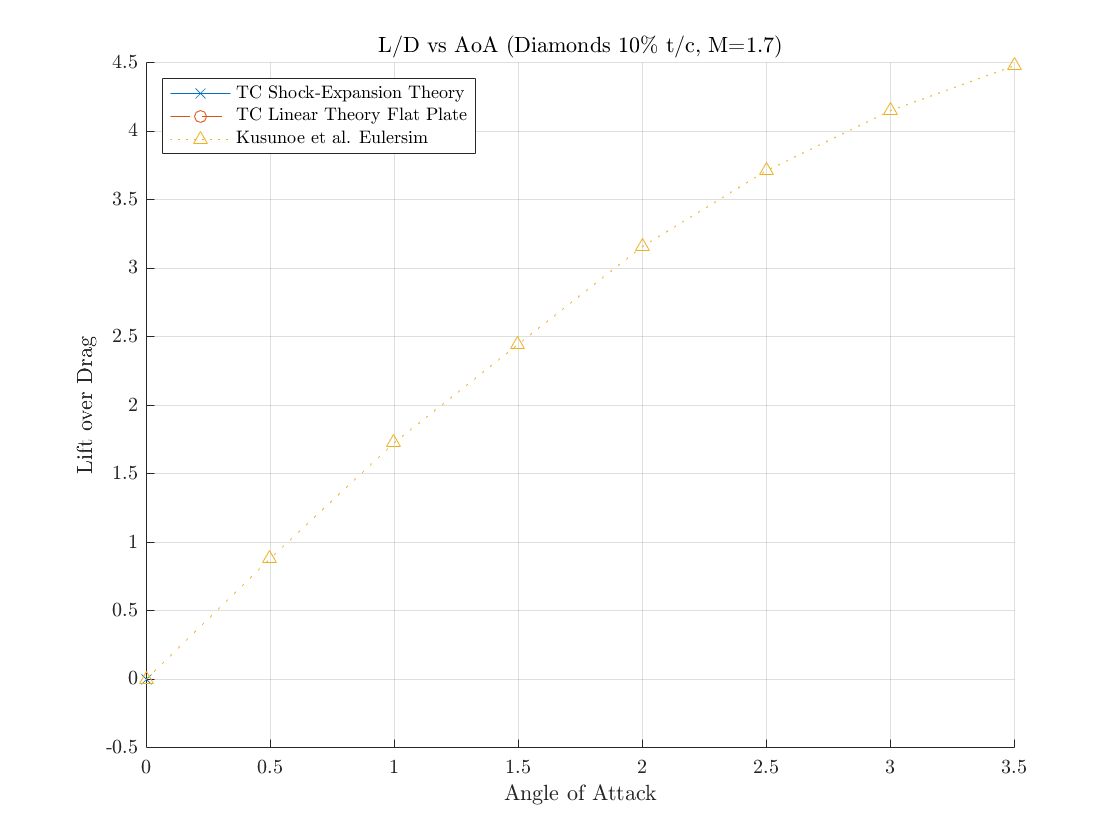


figure
plot(alphas,LoverD_SE,'x-')
hold on
plot(alphas,LoverD_flat,'o--')
hold on
plot(Jpn_alphas,Jpn_dia_LoverD_euler,'^:')
xlabel("Angle of Attack")
ylabel("Lift over Drag")
title("L/D vs AoA (Diamonds 10\% t/c, M=1.7)",'LineWidth',1.5)
legend("TC Shock-Expansion Theory","TC Linear Theory Flat Plate", "Kusunoe et al. Eulersim", "Location","northwest","NumColumns",1)
box off
grid on
hold off

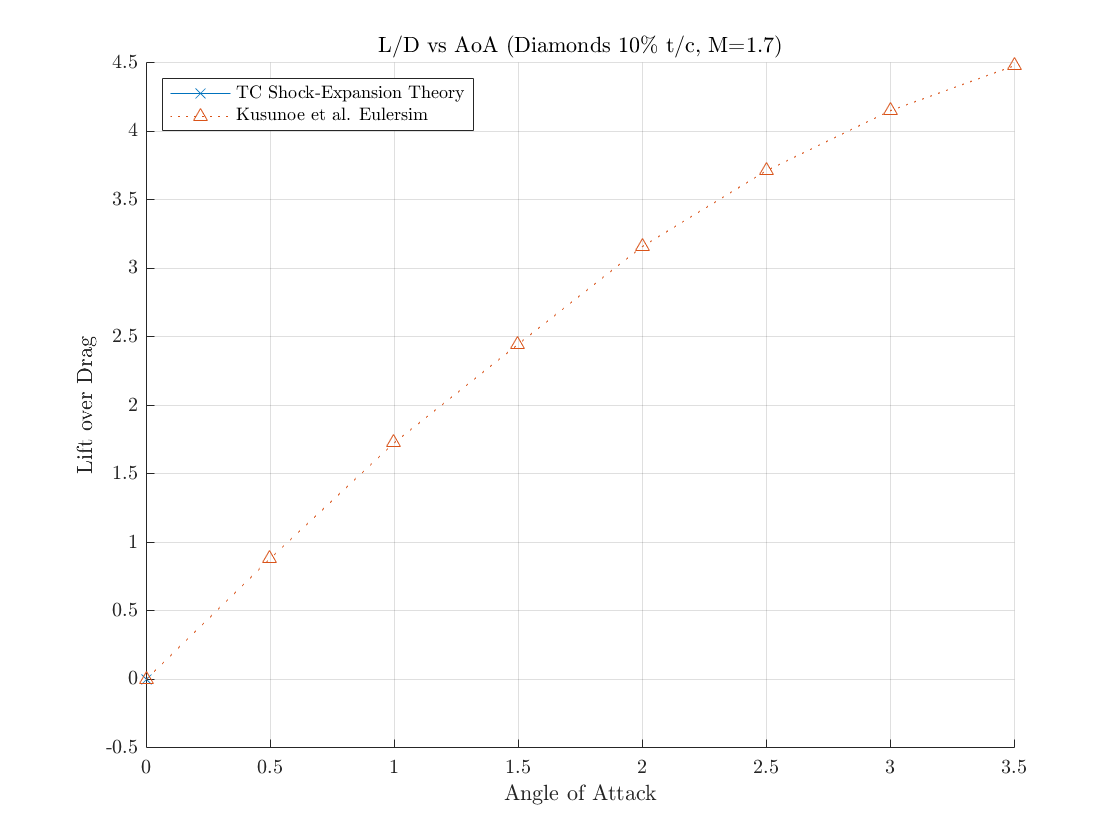

figure
plot(alphas,LoverD_SE,'x-')

hold on
plot(Jpn_alphas,Jpn_dia_LoverD_euler,'^:')
xlabel("Angle of Attack")
ylabel("Lift over Drag")
title("L/D vs AoA (Diamonds 10\% t/c, M=1.7)")
legend("TC Shock-Expansion Theory", "Kusunoe et al. Eulersim", "Location","northwest","NumColumns",1)
box off
grid on
hold off

function [C_L,C_D] = ShockExpansion_Diamond(M,chord,toverc,alfa)
%function [C_L,C_D] 
% Function uses accurate Shock Expansion Theorey and returns the Lift and Drag Coefficients of a Diamond Airfoil of
% Half Angle Delta (Specified by thickness over chord), at Mach M for an angle of attack Alfa.

    % Inputs    
% M         Mach Number             Scalar, Dimensionless
% alfa      Angle of Attack         Scalar, Degrees
% chord     Chord Length            Scalar, Length in Meters
% toverc    Thickness over Chord    Scalar, Percent of Chord, gross

    % Outputs  
% C_L       Lift Coefficient        Scalar, Dimensionless
% C_D       Drag Coeficcient        Scalar, Dimensionless

delta = atand((toverc)/100);

% Oblique shock relations calculations adapted from:
% https://www.mathworks.com/matlabcentral/fileexchange/28242-oblique-shock-relations-solver
% and https://github.com/guymargalit/shock-expansion

%% Define constants %%
gamma = 1.4;
if(delta == 0) %we have a flat plate
    %% Calculate nu, the prandtl Myer Function %%
    nu_inf = sqrt((gamma+1)/(gamma-1))*atand(sqrt(((gamma-1)/(gamma+1))*(M^2 - 1))) - atand(sqrt(M^2 - 1));
    nu = nu_inf + alfa;

    %% Solve for mach, T1/T_inf, and p1/p_inf %%
    syms x
    M1 = abs(vpasolve(nu == sqrt(6)*(atan(sqrt((1/6)*(x^2 - 1)))*(180/pi)) - (atan(sqrt(x^2 - 1))*(180/pi)),x));
    T1 = (1+((1.4-1)/2)*(M^2))/(1+((1.4-1)/2)*M1^2);
    p1 = double((T1)^((1.4)/(1.4-1)));

    %% Solve for beta with oblique shock relations %%
    theta = alfa;
    LHS = tan(theta*pi/180);
    beta = 1;
    RHS = inline('2*cot(beta*pi/180)*((M*sin(beta*pi/180))^2-1)/(M^2*(1.4+cos(2*beta*pi/180))+2)','beta','M');
    counter = 0;
    while (RHS(beta,M) < LHS*0.98 | RHS(beta,M) > LHS*1.02)
        if (beta > 90 | beta < 0 | counter >200)
            break;
        end
        if (RHS(beta,M) < LHS*0.70)
            beta=beta+1;
        elseif(RHS(beta,M) < LHS*0.90)
            beta=beta+0.5;
        elseif(RHS(beta,M) < LHS*0.95)
            beta=beta+0.3;
        elseif(RHS(beta,M) < LHS*0.98)
            beta=beta+0.1;
        end
        
        if(RHS(beta,M) > LHS*1.03)
            beta=beta-0.1;
        elseif(RHS(beta,M) > LHS*1.10)
            beta = beta-0.5;
        end
        counter = counter+1;   
    end
    
    counter = 0;
    
    while (RHS(beta,M) < LHS*0.99 | RHS(beta,M) > LHS*1.01)
        if (beta > 90 | beta < 0 | counter > 100)
            break;
        end
        if (RHS(beta,M) < LHS*0.98)
            beta=beta+0.05;
        elseif(RHS(beta,M) < LHS*0.985)
            beta=beta+0.03;
        elseif(RHS(beta,M) < LHS*0.99)
            beta=beta+0.01;
        end
        
        if(RHS(beta,M) > LHS*1.01)
            beta=beta-0.01;
        elseif(RHS(beta,M) > LHS*1.02)
            beta = beta-0.1;
        end
        counter = counter+1;
    end
    
    counter = 0;
    
    while (RHS(beta,M) ~= LHS)
        if (beta > 90 | beta < 0 | counter > 40)
            break;
        end
        
        if (RHS(beta,M) < LHS)
            beta=beta+0.005;
        end
        if(RHS(beta,M) > LHS)
            beta=beta-0.005;
        end
        counter = counter+1;
    end
    
    if (beta < 0)
        fprintf('Beta not in bounds');
    end

    %% Solve for mach and p2/p_inf %%
    M2 = M*sind(beta);
    p2 = 1 + ((2*gamma)/(gamma+1))*(M2^2 - 1);

    %% Calculate c_l and c_d %%
    C_L = (2/(gamma*(M^2)))*(p2 - p1)*cosd(alfa);
    C_D = (2/(gamma*(M^2)))*(p2 - p1)*sind(alfa);
    
elseif(alfa >= 0 && alfa < delta)
    %% Find p1/p_inf with oblique shock relations %%
    theta = delta-alfa;
    LHS = tan(theta*pi/180);
    beta = 1;
    RHS = inline('2*cot(beta*pi/180)*((M*sin(beta*pi/180))^2-1)/(M^2*(1.4+cos(2*beta*pi/180))+2)','beta','M');
    counter = 0;
    while (RHS(beta,M) < LHS*0.98 | RHS(beta,M) > LHS*1.02)
        if (beta > 90 | beta < 0 | counter >200)
            break;
        end
        if (RHS(beta,M) < LHS*0.70)
            beta=beta+1;
        elseif(RHS(beta,M) < LHS*0.90)
            beta=beta+0.5;
        elseif(RHS(beta,M) < LHS*0.95)
            beta=beta+0.3;
        elseif(RHS(beta,M) < LHS*0.98)
            beta=beta+0.1;
        end
        
        if(RHS(beta,M) > LHS*1.03)
            beta=beta-0.1;
        elseif(RHS(beta,M) > LHS*1.10)
            beta = beta-0.5;
        end
        counter = counter+1;   
    end
    
    counter = 0;
    
    while (RHS(beta,M) < LHS*0.99 | RHS(beta,M) > LHS*1.01)
        if (beta > 90 | beta < 0 | counter > 100)
            break;
        end
        if (RHS(beta,M) < LHS*0.98)
            beta=beta+0.05;
        elseif(RHS(beta,M) < LHS*0.985)
            beta=beta+0.03;
        elseif(RHS(beta,M) < LHS*0.99)
            beta=beta+0.01;
        end
        
        if(RHS(beta,M) > LHS*1.01)
            beta=beta-0.01;
        elseif(RHS(beta,M) > LHS*1.02)
            beta = beta-0.1;
        end
        counter = counter+1;
    end
    
    counter = 0;
    
    while (RHS(beta,M) ~= LHS)
        if (beta > 90 | beta < 0 | counter > 40)
            break;
        end
        
        if (RHS(beta,M) < LHS)
            beta=beta+0.005;
        end
        if(RHS(beta,M) > LHS)
            beta=beta-0.005;
        end
        counter = counter+1;
    end
    
    if (beta < 0)
        fprintf('Beta not in bounds');
    end
    Mn_inf = M*sind(beta);
    p1 = double(1 + ((2*gamma)/(gamma+1))*(Mn_inf^2 - 1));
    Mn1 = sqrt((1+((gamma-1)/2)*Mn_inf^2)/(gamma*Mn_inf^2 - (gamma-1)/2));
    M1 = Mn1/(sind(beta-(theta)));
    nu1 = sqrt((gamma+1)/(gamma-1))*atand(sqrt(((gamma-1)/(gamma+1))*(M1^2 - 1))) - atand(sqrt(M1^2 - 1));
    
    %% Find p2/p_inf with expansion fan %%
    nu2 = nu1 + (2*delta);
    syms x
    M2 = abs(vpasolve(nu2 == sqrt(6)*(atan(sqrt((1/6)*(x^2 - 1)))*(180/pi)) - (atan(sqrt(x^2 - 1))*(180/pi)),x));
    T2 = (1+((1.4-1)/2)*(M1^2))/(1+((1.4-1)/2)*M2^2);
    p2p1 = double((T2)^((1.4)/(1.4-1)));
    p2 = (p2p1)*p1;
    
    %% Find p3/p_inf with oblique shock relations %%
    theta = delta + alfa;
    LHS = tan(theta*pi/180);
    beta = 1;
    RHS = inline('2*cot(beta*pi/180)*((M*sin(beta*pi/180))^2-1)/(M^2*(1.4+cos(2*beta*pi/180))+2)','beta','M');
    counter = 0;
    while (RHS(beta,M) < LHS*0.98 | RHS(beta,M) > LHS*1.02)
        if (beta > 90 | beta < 0 | counter >200)
            break;
        end
        if (RHS(beta,M) < LHS*0.70)
            beta=beta+1;
        elseif(RHS(beta,M) < LHS*0.90)
            beta=beta+0.5;
        elseif(RHS(beta,M) < LHS*0.95)
            beta=beta+0.3;
        elseif(RHS(beta,M) < LHS*0.98)
            beta=beta+0.1;
        end
        
        if(RHS(beta,M) > LHS*1.03)
            beta=beta-0.1;
        elseif(RHS(beta,M) > LHS*1.10)
            beta = beta-0.5;
        end
        counter = counter+1;   
    end
    
    counter = 0;
    
    while (RHS(beta,M) < LHS*0.99 | RHS(beta,M) > LHS*1.01)
        if (beta > 90 | beta < 0 | counter > 100)
            break;
        end
        if (RHS(beta,M) < LHS*0.98)
            beta=beta+0.05;
        elseif(RHS(beta,M) < LHS*0.985)
            beta=beta+0.03;
        elseif(RHS(beta,M) < LHS*0.99)
            beta=beta+0.01;
        end
        
        if(RHS(beta,M) > LHS*1.01)
            beta=beta-0.01;
        elseif(RHS(beta,M) > LHS*1.02)
            beta = beta-0.1;
        end
        counter = counter+1;
    end
    
    counter = 0;
    
    while (RHS(beta,M) ~= LHS)
        if (beta > 90 | beta < 0 | counter > 40)
            break;
        end
        
        if (RHS(beta,M) < LHS)
            beta=beta+0.005;
        end
        if(RHS(beta,M) > LHS)
            beta=beta-0.005;
        end
        counter = counter+1;
    end
    
    if (beta < 0)
        fprintf('Beta not in bounds');
    end
    Mn_inf = M*sind(beta);
    p3 = double(1 + ((2*gamma)/(gamma+1))*(Mn_inf^2 - 1));
    Mn3 = sqrt((1+((gamma-1)/2)*Mn_inf^2)/(gamma*Mn_inf^2 - (gamma-1)/2));
    M3 = Mn3/(sind(beta-(theta)));
    
    %% Find p4/p_inf with expansion fan %%
    nu3 = sqrt((gamma+1)/(gamma-1))*atand(sqrt(((gamma-1)/(gamma+1))*(M3^2 - 1))) - atand(sqrt(M3^2 - 1));
    nu4 = nu3 + (2*delta);
    syms x
    M4 = abs(vpasolve(nu4 == sqrt(6)*(atan(sqrt((1/6)*(x^2 - 1)))*(180/pi)) - (atan(sqrt(x^2 - 1))*(180/pi)),x));
    T4 = (1+((1.4-1)/2)*(M3^2))/(1+((1.4-1)/2)*M4^2);
    p4p3 = double((T4)^((1.4)/(1.4-1)));
    p4 = (p4p3)*p3;
    
    %% Compute c_n and c_a %%
    c_n = (1/(gamma*M^2))*(-p1 - p2 + p3 + p4);
    c_a = (1/(gamma*M^2))*(p1 - p2 + p3 - p4)*tand(delta);
    
    %% Compute c_l and c_d %%
    C_L = c_n*cosd(alfa) - c_a*sind(alfa);
    C_D = c_n*sind(alfa) + c_a*cosd(alfa);

elseif(alfa == delta)
    %% Find p1/p_inf %%
    nu_inf = sqrt((gamma+1)/(gamma-1))*atand(sqrt(((gamma-1)/(gamma+1))*(M^2 - 1))) - atand(sqrt(M^2 - 1));
    nu1 = nu_inf;
    syms x
    M1 = abs(vpasolve(nu1 == sqrt(6)*(atan(sqrt((1/6)*(x^2 - 1)))*(180/pi)) - (atan(sqrt(x^2 - 1))*(180/pi)),x));
    p1 = 1;
    %% Find p2/p_inf with expansion fan %%
    nu2 = nu1 + (2*delta);
    syms x
    M2 = abs(vpasolve(nu2 == sqrt(6)*(atan(sqrt((1/6)*(x^2 - 1)))*(180/pi)) - (atan(sqrt(x^2 - 1))*(180/pi)),x));
    T2 = (1+((1.4-1)/2)*(M1^2))/(1+((1.4-1)/2)*M2^2);
    p2p1 = double((T2)^((1.4)/(1.4-1)));
    p2 = (p2p1)*p1;
    
    %% Find p3/p_inf with oblique shock relations %%
    theta = (2*delta);
    LHS = tan(theta*pi/180);
    beta = 1;
    RHS = inline('2*cot(beta*pi/180)*((M*sin(beta*pi/180))^2-1)/(M^2*(1.4+cos(2*beta*pi/180))+2)','beta','M');
    counter = 0;
    while (RHS(beta,M) < LHS*0.98 | RHS(beta,M) > LHS*1.02)
        if (beta > 90 | beta < 0 | counter >200)
            break;
        end
        if (RHS(beta,M) < LHS*0.70)
            beta=beta+1;
        elseif(RHS(beta,M) < LHS*0.90)
            beta=beta+0.5;
        elseif(RHS(beta,M) < LHS*0.95)
            beta=beta+0.3;
        elseif(RHS(beta,M) < LHS*0.98)
            beta=beta+0.1;
        end
        
        if(RHS(beta,M) > LHS*1.03)
            beta=beta-0.1;
        elseif(RHS(beta,M) > LHS*1.10)
            beta = beta-0.5;
        end
        counter = counter+1;   
    end
    
    counter = 0;
    
    while (RHS(beta,M) < LHS*0.99 | RHS(beta,M) > LHS*1.01)
        if (beta > 90 | beta < 0 | counter > 100)
            break;
        end
        if (RHS(beta,M) < LHS*0.98)
            beta=beta+0.05;
        elseif(RHS(beta,M) < LHS*0.985)
            beta=beta+0.03;
        elseif(RHS(beta,M) < LHS*0.99)
            beta=beta+0.01;
        end
        
        if(RHS(beta,M) > LHS*1.01)
            beta=beta-0.01;
        elseif(RHS(beta,M) > LHS*1.02)
            beta = beta-0.1;
        end
        counter = counter+1;
    end
    
    counter = 0;
    
    while (RHS(beta,M) ~= LHS)
        if (beta > 90 | beta < 0 | counter > 40)
            break;
        end
        
        if (RHS(beta,M) < LHS)
            beta=beta+0.005;
        end
        if(RHS(beta,M) > LHS)
            beta=beta-0.005;
        end
        counter = counter+1;
    end
    
    if (beta < 0)
        fprintf('Beta not in bounds');
    end
    Mn_inf = M*sind(beta);
    p3 = double(1 + ((2*gamma)/(gamma+1))*(Mn_inf^2 - 1));
    Mn3 = sqrt((1+((gamma-1)/2)*Mn_inf^2)/(gamma*Mn_inf^2 - (gamma-1)/2));
    M3 = Mn3/(sind(beta-(theta)));
    
    %% Find p4/p_inf with expansion fan %%
    nu3 = sqrt((gamma+1)/(gamma-1))*atand(sqrt(((gamma-1)/(gamma+1))*(M3^2 - 1))) - atand(sqrt(M3^2 - 1));
    nu4 = nu3 + (2*delta);
    syms x
    M4 = abs(vpasolve(nu4 == sqrt(6)*(atan(sqrt((1/6)*(x^2 - 1)))*(180/pi)) - (atan(sqrt(x^2 - 1))*(180/pi)),x));
    T4 = (1+((1.4-1)/2)*(M3^2))/(1+((1.4-1)/2)*M4^2);
    p4p3 = double((T4)^((1.4)/(1.4-1)));
    p4 = (p4p3)*p3;
    
    %% Compute c_n and c_a %%
    c_n = (1/(gamma*M^2))*(-p1 - p2 + p3 + p4);
    c_a = (1/(gamma*M^2))*(p1 - p2 + p3 - p4)*tand(delta);
    
    %% Compute c_l and c_d %%
    C_L = c_n*cosd(alfa) - c_a*sind(alfa);
    C_D = c_n*sind(alfa) + c_a*cosd(alfa);
    
elseif(alfa > delta)
    %% Find p1/p_inf with expansion fan %%
    nu_inf = sqrt((gamma+1)/(gamma-1))*atand(sqrt(((gamma-1)/(gamma+1))*(M^2 - 1))) - atand(sqrt(M^2 - 1));
    nu1 = nu_inf + (alfa-delta);
    syms x
    M1 = abs(vpasolve(nu1 == sqrt(6)*(atan(sqrt((1/6)*(x^2 - 1)))*(180/pi)) - (atan(sqrt(x^2 - 1))*(180/pi)),x));
    T1 = (1+((1.4-1)/2)*(M^2))/(1+((1.4-1)/2)*M1^2);
    p1 = double((T1)^((1.4)/(1.4-1)));
    
    %% Find p2/p_inf with expansion fan %%
    nu2 = nu1 + (2*delta);
    syms x
    M2 = abs(vpasolve(nu2 == sqrt(6)*(atan(sqrt((1/6)*(x^2 - 1)))*(180/pi)) - (atan(sqrt(x^2 - 1))*(180/pi)),x));
    T2 = (1+((1.4-1)/2)*(M1^2))/(1+((1.4-1)/2)*M2^2);
    p2p1 = double((T2)^((1.4)/(1.4-1)));
    p2 = (p2p1)*p1;
    
    %% Find p3/p_inf with oblique shock relations %%
    theta = (alfa+delta);
    LHS = tan(theta*pi/180);
    beta = 1;
    RHS = inline('2*cot(beta*pi/180)*((M*sin(beta*pi/180))^2-1)/(M^2*(1.4+cos(2*beta*pi/180))+2)','beta','M');
    counter = 0;
    while (RHS(beta,M) < LHS*0.98 | RHS(beta,M) > LHS*1.02)
        if (beta > 90 | beta < 0 | counter >200)
            break;
        end
        if (RHS(beta,M) < LHS*0.70)
            beta=beta+1;
        elseif(RHS(beta,M) < LHS*0.90)
            beta=beta+0.5;
        elseif(RHS(beta,M) < LHS*0.95)
            beta=beta+0.3;
        elseif(RHS(beta,M) < LHS*0.98)
            beta=beta+0.1;
        end
        
        if(RHS(beta,M) > LHS*1.03)
            beta=beta-0.1;
        elseif(RHS(beta,M) > LHS*1.10)
            beta = beta-0.5;
        end
        counter = counter+1;   
    end
    
    counter = 0;
    
    while (RHS(beta,M) < LHS*0.99 | RHS(beta,M) > LHS*1.01)
        if (beta > 90 | beta < 0 | counter > 100)
            break;
        end
        if (RHS(beta,M) < LHS*0.98)
            beta=beta+0.05;
        elseif(RHS(beta,M) < LHS*0.985)
            beta=beta+0.03;
        elseif(RHS(beta,M) < LHS*0.99)
            beta=beta+0.01;
        end
        
        if(RHS(beta,M) > LHS*1.01)
            beta=beta-0.01;
        elseif(RHS(beta,M) > LHS*1.02)
            beta = beta-0.1;
        end
        counter = counter+1;
    end
    
    counter = 0;
    
    while (RHS(beta,M) ~= LHS)
        if (beta > 90 | beta < 0 | counter > 40)
            break;
        end
        
        if (RHS(beta,M) < LHS)
            beta=beta+0.005;
        end
        if(RHS(beta,M) > LHS)
            beta=beta-0.005;
        end
        counter = counter+1;
    end
    
    if (beta < 0)
        fprintf('Beta not in bounds');
    end
    
    Mn_inf = M*sind(beta);
    p3 = double(1 + ((2*gamma)/(gamma+1))*(Mn_inf^2 - 1));
    Mn3 = sqrt((1+((gamma-1)/2)*Mn_inf^2)/(gamma*Mn_inf^2 - (gamma-1)/2));
    M3 = Mn3/(sind(beta-(theta)));
    
    %% Find p4/p_inf with expansion fan %%
    nu3 = sqrt((gamma+1)/(gamma-1))*atand(sqrt(((gamma-1)/(gamma+1))*(M3^2 - 1))) - atand(sqrt(M3^2 - 1));
    nu4 = nu3 + (2*delta);
    syms x
    M4 = abs(vpasolve(nu4 == sqrt(6)*(atan(sqrt((1/6)*(x^2 - 1)))*(180/pi)) - (atan(sqrt(x^2 - 1))*(180/pi)),x));
    T4 = (1+((1.4-1)/2)*(M3^2))/(1+((1.4-1)/2)*M4^2);
    p4p3 = double((T4)^((1.4)/(1.4-1)));
    p4 = (p4p3)*p3;
    
    %% Compute c_n and c_a %%
    c_n = (1/(gamma*M^2))*(-p1 - p2 + p3 + p4);
    c_a = (1/(gamma*M^2))*(p1 - p2 + p3 - p4)*tand(delta);
    
    %% Compute c_l and c_d %%
    C_L = c_n*cosd(alfa) - c_a*sind(alfa);
    C_D = c_n*sind(alfa) + c_a*cosd(alfa);
    
    %P_out =[p1,p2,p3,p4];
    %M_out =double([M1,M2,M3,M4]);
    format
    
end
end
